# Solutions to Exercises on Constrained Polynomial Approximation (03.12.2024)

Course: Data Science for Engineers II

Author: Dimitar Ninevski

Date: 09.12.2024

## Prepare workspace

close all;
clear;

## Question 1

### Part a. 

First we load the dataset

load cantileverWithSupportMeasData.mat;

The next step is to rescale the data, so we don't have any issues with the approximation.

x = x';
y = y';
x = normalize(x, 'range', [-1 1]);

Now we create the Vandermonde matrix

degree = 6;
vFull = vander(x);
V = vFull(:, end-degree:end);

In order to obtain the constraint matrix C, we need to take the rows from the matrix V where the constraints are happening.

C = V([1 61], :);
N = null(C);
alphaVC = N*pinv(V*N)*y;

### Part b.

Let's compute coefficients with just the derivative constraints.

In order to do that, we need to compute the derivative of the Vandermonde matrix first.

d = degree:-1:1;
M = diag(d, -1);
dV = V*M;

Now we can define the constraint matrix dC in the case of the derivatives.

dC = dV(1, :);
dN = null(dC);
alphaDC = dN*pinv(V*dN)*y;

Now we can compare the results visually.

First, compute the x values for the visualization

xMin = min(x);
xMax = max(x);
nrPts = 1000;
xPlot = linspace(xMin, xMax, nrPts);

Now we compute the two polynomials.

yPlotVC = polyval(alphaVC, xPlot);
yPlotDC = polyval(alphaDC, xPlot);

Finally, let's plot it all. I will also mark the location of the constraint

figure
plot(x, y, '.', 'MarkerSize',8);
hold on;
plot(x(61), 0, 'ro', 'MarkerSize', 5)
plot(xPlot, yPlotVC,'--', 'LineWidth',2);
plot(xPlot, yPlotDC,'-.', 'LineWidth',2);
grid on;
xlabel('x');
ylabel('y');

We can see that there are small differences, mostly around the start and around the constraint location at 61, which is expected.

### Part c.

Now we need to combine the two constraint matrices from above into one.

Call = [C; dC];
Nall = null(Call);
alphaall = Nall*pinv(V*Nall)*y;

Not plotting this, because the results are gonna be lost in the plot, but you get the idea.

### Part d. 

This is the same as the first derivative, we just need to define the second derivative matrix ddV first. We will try two different ways and compare the results.

The first approach, is to define a matrix M2 (similar to M) and multiply the Vandermonde matrix with that. 

dd = (degree:-1:2).*(degree-1:-1:1);
M2 = diag(dd, -2);
ddV1 = V*M2;

The second approach is to take the derivative of the derivative of the Vandermonde matrix.

ddV2 = V*M*M;

We can see that the matrices are the same up to the 15th decimal place, which means that any differences are purely numerical and we can conclude that they are the same. I personally prefer the second approach, cause it's faster but now you know there are two.

ddC = ddV2(end, :);
Cfull = [Call; ddC];
Nfull = null(Cfull);
alphafull = Nfull*pinv(V*Nfull)*y;

Let's plot this result, adding it to the other plots.

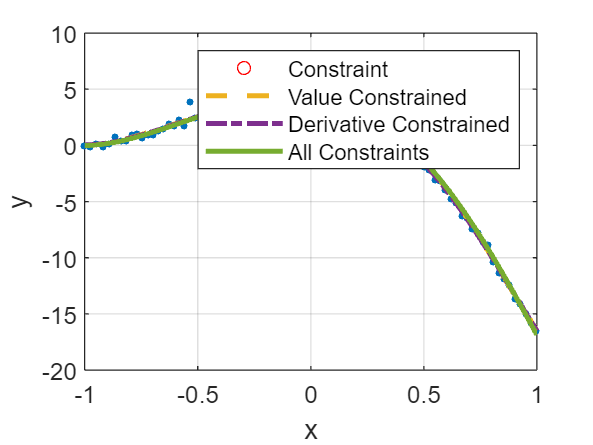

yPlotFull = polyval(alphafull, xPlot);
plot(xPlot, yPlotFull, 'LineWidth', 2)
legend('','Constraint', 'Value Constrained', 'Derivative Constrained', 'All Constraints')

The differences between the plots are minimal, but mostly due to the dataset and the nature of the constraints. 

## Question 2

Let's try the Lagrange multiplier method with just the value constraints.

The problem can be formulated as finding the minimum of the following function


$$L(\alpha, \lambda_1, \lambda_2) = \|y - V \alpha\| - \lambda_1p(1) - \lambda_2p(61)$$


where the unknown coefficients$\alpha$ are also found in the expressions$p(1), p(61)$.

We will do this using the fminsearch function in MATLAB.

First we need to define a function (which we need to minimize)

Lagrange = @(beta)norm(y-V*beta(1:7)) - beta(8:9)'*(C*beta(1:7));

This is called an anonymous function in MATLAB.

The @(beta) means that we are defining a function with the input "beta". The expression in the brackets is the actual function. One thing to note, is that the beta in the function contains ALL unknown parameters, in our case both alpha and lambda.

norm(y-V*beta(1:7)) is equal to $\|y - V \alpha\| $.

beta(8:9)'*(C*beta(1:7)) can be written as beta(8)*first constraint + beta(9)*second constraint. This is equivalent to $\lambda_1p(1) - \lambda_2p(61)$. 

Now that the function is defined, we can minimize it. We need to also define some initial values for the nonlinear optimization to start. I have taken some values here that seem to work. This can be done via guessing, more or less educated. In our case, the initial values are a bunch of -10s for the polynomial coefficients, and zeros for the lambdas.

Alternatively, we can use the coefficients from the unconstrained polynomial approximation as a starting point.

startVal = -10*[ones(size(alphaVC)); zeros(3,1)];
%startVal = [pinv(V)*y; -.0000000000001*ones(3, 1)];
values = fminsearch(Lagrange, startVal);

We can now compare the values we computed with the Lagrange multiplier method, and the ones from before, in alphaVC.

alphaLag = values(1:length(alphaVC));
alphaVC - alphaLag

ans =     2.2172
    0.6288
   -3.2885
   -1.0102
    1.1713
    0.3828
   -0.0121


Let's plot both results

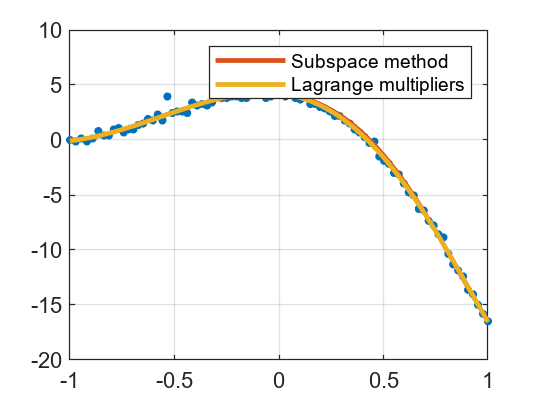

yPlotLag = polyval(alphaLag, xPlot);
figure
plot(x, y, '.','MarkerSize', 12);
hold on;
plot(xPlot, yPlotVC, 'LineWidth', 2);
plot(xPlot, yPlotLag, 'LineWidth', 2);
grid on;
legend('','Subspace method', 'Lagrange multipliers')

Conclusion: This method is very reliant on the initial value chosen. Additionally, the constraints aren't actually fulfilled, since their fulfillment depends on the lambda coefficients that we end up getting. This kind of constraint fulfillment is sometimes called "soft constraints", because the function doesn't actually do what we need it to do, but it gets close to it. 

So, this method is good for more complicated problems, where other possibilities don't work, but in our case we have a much faster and much more reliable way of dealing with the constraints.